## Neural Time-Series Analysis Lab module

*A) Generate a time series by creating and summing sine waves, as in figure 1B. Use four sine waves, so that the individual sine waves are still somewhat visible in the sum. Perform a Fourier analysis on the resulting time series and plot the power structure. Confirm that your code is correct by comparing the frequencies with nonzero power to the frequencies of the sine waves that you generated. *

Fs = 1000;  % Sampling frequencies
T = 1/Fs;   % Sampling period
L = 1000;   % Length of signal
t = (0:L-1)*T;  % Time vector
% Frequencies
f1 = 1;
f2 = 10;
f3 = 50;
f4 = 100;
% Amplitude
amp = 10;
% Phrase;
phi = 0;

%Define the sinewaves
y1 = amp * sin(2*pi*f1*t + phi);
y2 = amp * sin(2*pi*f2*t + phi);
y3 = amp * sin(2*pi*f3*t + phi);
y4 = amp * sin(2*pi*f4*t + phi);

Now visualize these waves in subplots:

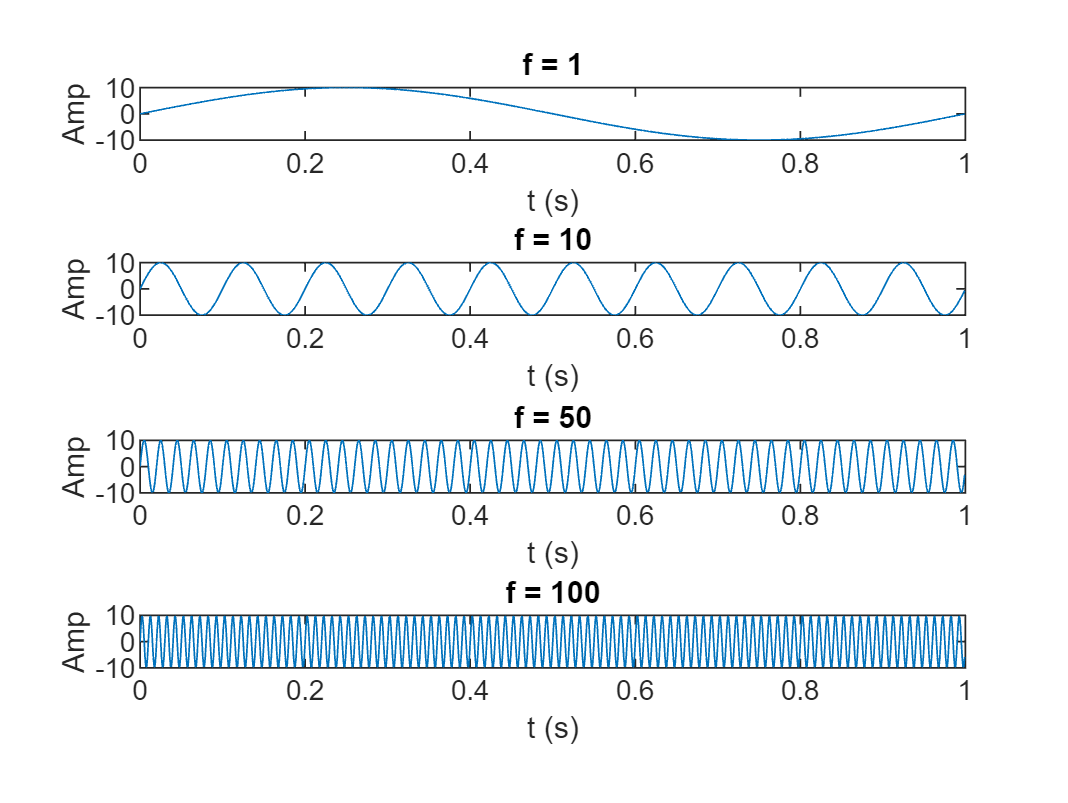

% Subplots
subplot(4, 1, 1)
plot(t, y1)
xlabel("t (s)")
ylabel("Amp")
title("f = 1")

subplot(4, 1, 2)
plot(t, y2)
xlabel("t (s)")
ylabel("Amp")
title("f = 10")

subplot(4, 1, 3)
plot(t, y3)
xlabel("t (s)")
ylabel("Amp")
title("f = 50")

subplot(4, 1, 4)
plot(t, y4)
xlabel("t (s)")
ylabel("Amp")
title("f = 100")

Now sum these four waves together:

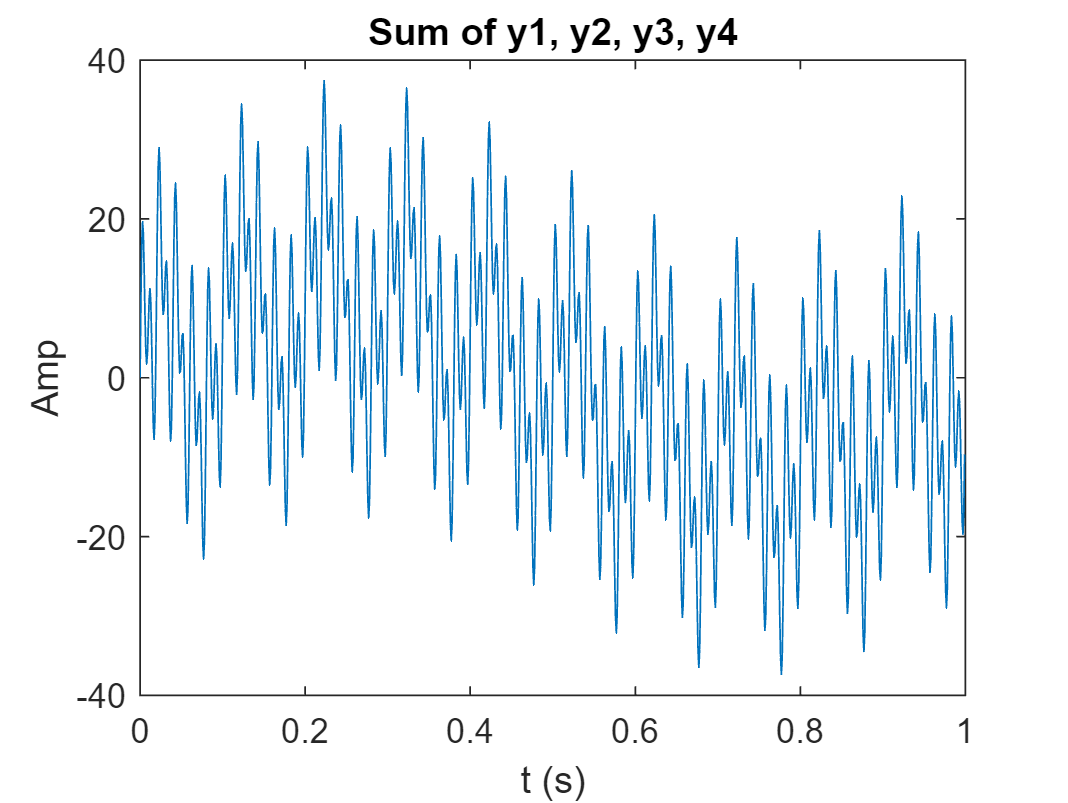

y_sum = y1 + y2 + y3 + y4;
% New figure
figure
plot(t, y_sum)
xlabel("t (s)")
ylabel("Amp")
title("Sum of y1, y2, y3, y4")

Now do the Fourier Transform and Visualize the power structure:

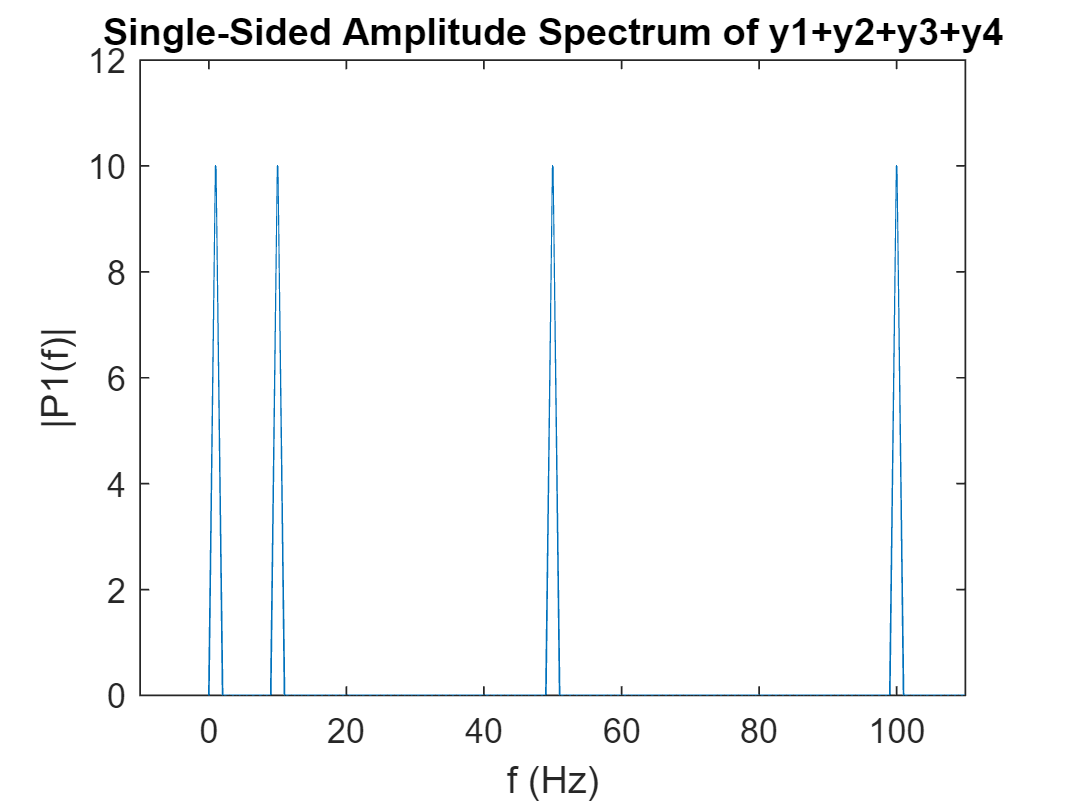

% Compute the two-sided spectrum p2.
% Then compute the single sided spectrum p1
% based on p2 and the even-valued signal lengh L
Y = fft(y_sum);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of y1+y2+y3+y4')
xlabel('f (Hz)')
ylabel('|P1(f)|')
axis([-10, 110, 0, 12])

As you can see, my code is correct since the frequencies with nonzero power is the same as the frequencies of he sine waves I generated.

B) Try adding random noise to the signal before computing the Fourier transform. First, add a small amount of noise so that the sine waves are still visually recognizable. Next, add a large amount of noise so that the sine waves are no longer visually recognizable in the time domain data. Perform a Fourier analysis on the two noisy signals and plot the results. What is the effect of a small and a large amount of noise in the power spectrum? Are the sine waves with noise easier to detect in the time domain or in the frequency domain, or is it equally easy/difficult to detect a sine wave in the presence of noise? Figure 1. Several sine waves of differing amplitudes, frequencies, and phases, plotted separately (panel A) and after being added together (panel B). 

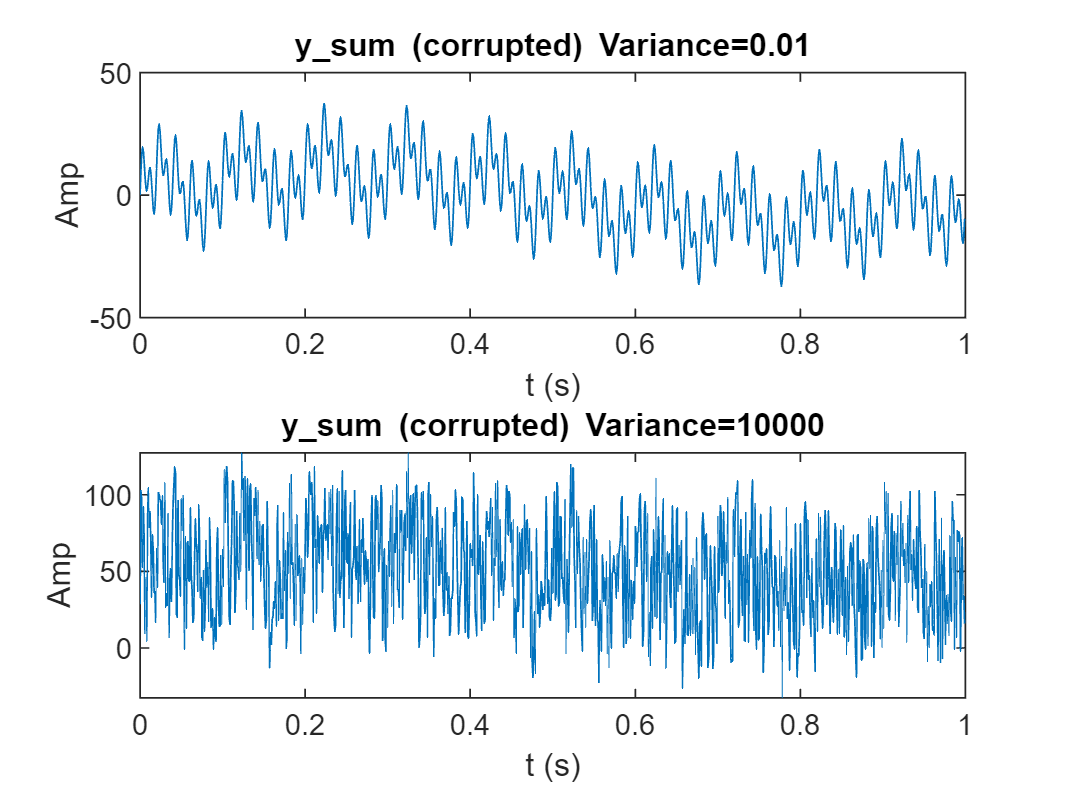

% Corrupt the y_sum with noise
% Small amount
y_corrupt1 = y_sum + 0.1*rand(size(t));
% Large amount
y_corrupt2 = y_sum + 100*rand(size(t));
figure
subplot(2, 1, 1)
plot(t, y_corrupt1)
xlabel("t (s)")
ylabel("Amp")
title("y\_sum (corrupted) Variance=0.01")

subplot(2, 1, 2)
plot(t, y_corrupt2)
xlabel("t (s)")
ylabel("Amp")
title("y\_sum (corrupted) Variance=10000")

As we can see that when the amount of the noise is small, the original shape of the signal is still recognizable. However when the amount of noise is large, the original signal is unrecognizable.

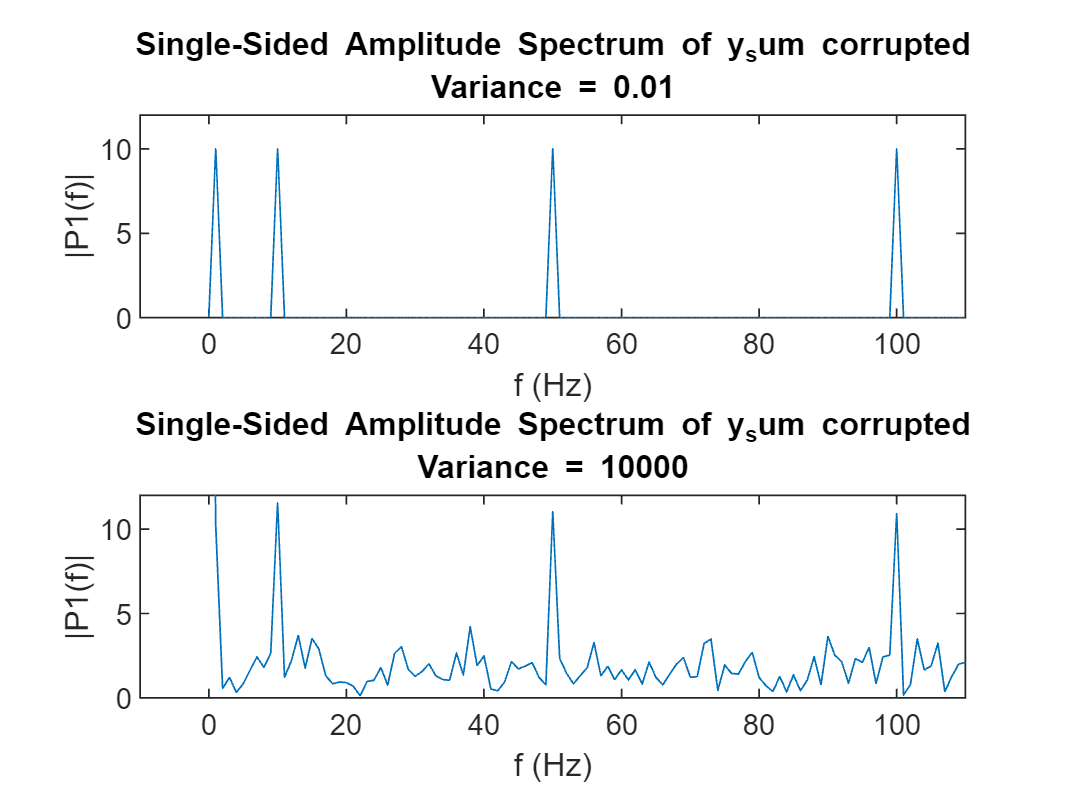

Y1 = fft(y_corrupt1);
P21 = abs(Y1/L);
P11 = P21(1:L/2+1);
P11(2:end-1) = 2*P11(2:end-1);

Y2 = fft(y_corrupt2);
P22 = abs(Y2/L);
P12 = P22(1:L/2+1);
P12(2:end-1) = 2*P12(2:end-1);

figure
subplot(2, 1, 1)
plot(f,P11) 
title(["Single-Sided Amplitude Spectrum of y_sum corrupted", ...
       "Variance = 0.01"])
xlabel('f (Hz)')
ylabel('|P1(f)|')
axis([-10, 110, 0, 12])

subplot(2, 1, 2)
plot(f,P12) 
title(["Single-Sided Amplitude Spectrum of y_sum corrupted", ...
       "Variance = 10000"])
xlabel('f (Hz)')
ylabel('|P1(f)|')
axis([-10, 110, 0, 12])

As you can see, it is much easier to detect the sine waves with noise in the frequency domain.

C) create a nonstationary time series (similar to the waveform in Figure 2) using the sine waves from section A, perform the Fourier analysis on the entire signal and plot the results

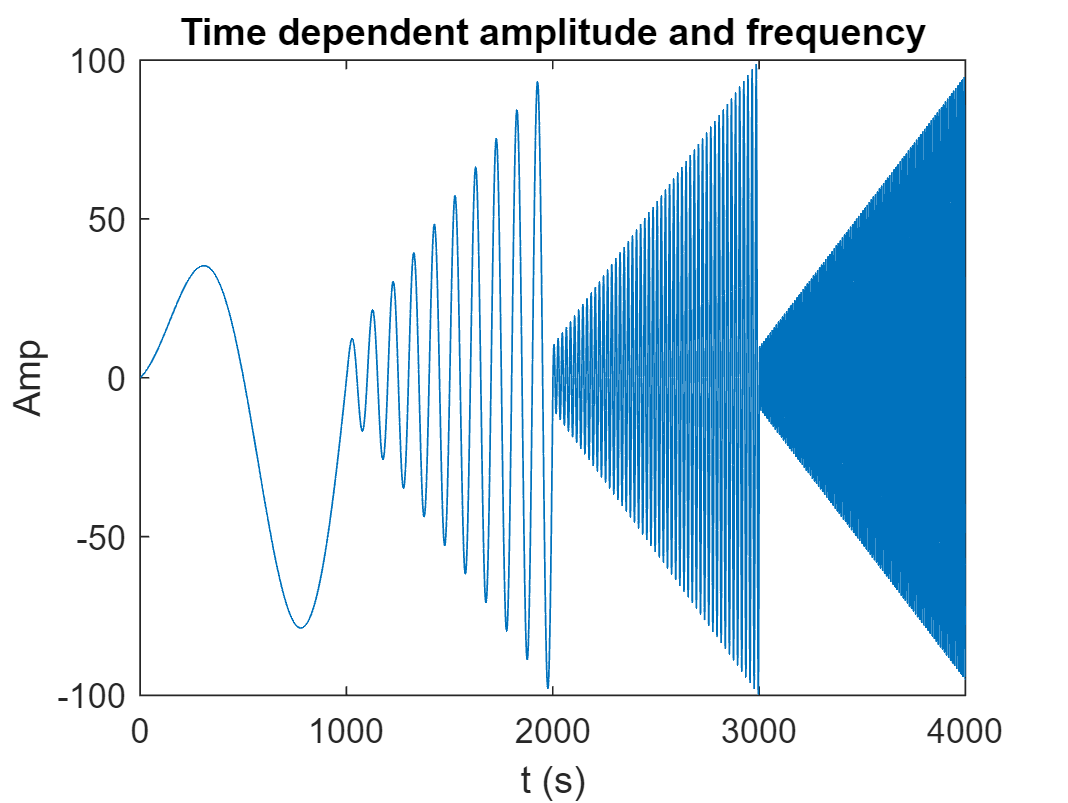

amp_ramp = 1 : 9/length(y1) : 10;
y_nonstat = [amp_ramp(1:1000) .* y1, amp_ramp(1:1000) .* y2,...
             amp_ramp(1:1000) .* y3,...
             amp_ramp(1:1000) .* y4];
t_nonstat = 1:length(y_nonstat);
figure
plot(t_nonstat, y_nonstat)
xlabel("t (s)")
ylabel("Amp")
title("Time dependent amplitude and frequency")

Perform the fft on the non stationary signal:

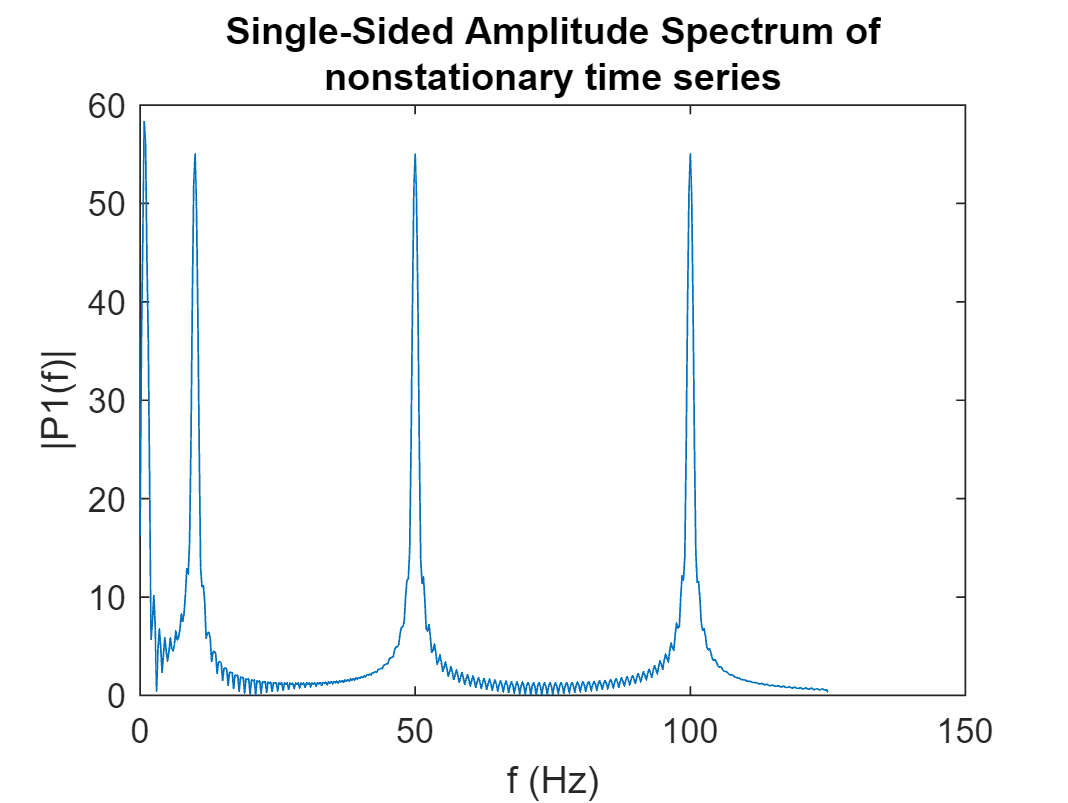

Y = fft(y_nonstat);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure
plot(f./4, P1) 
title(['Single-Sided Amplitude Spectrum of', "nonstationary time series"])
xlabel('f (Hz)')
ylabel('|P1(f)|')

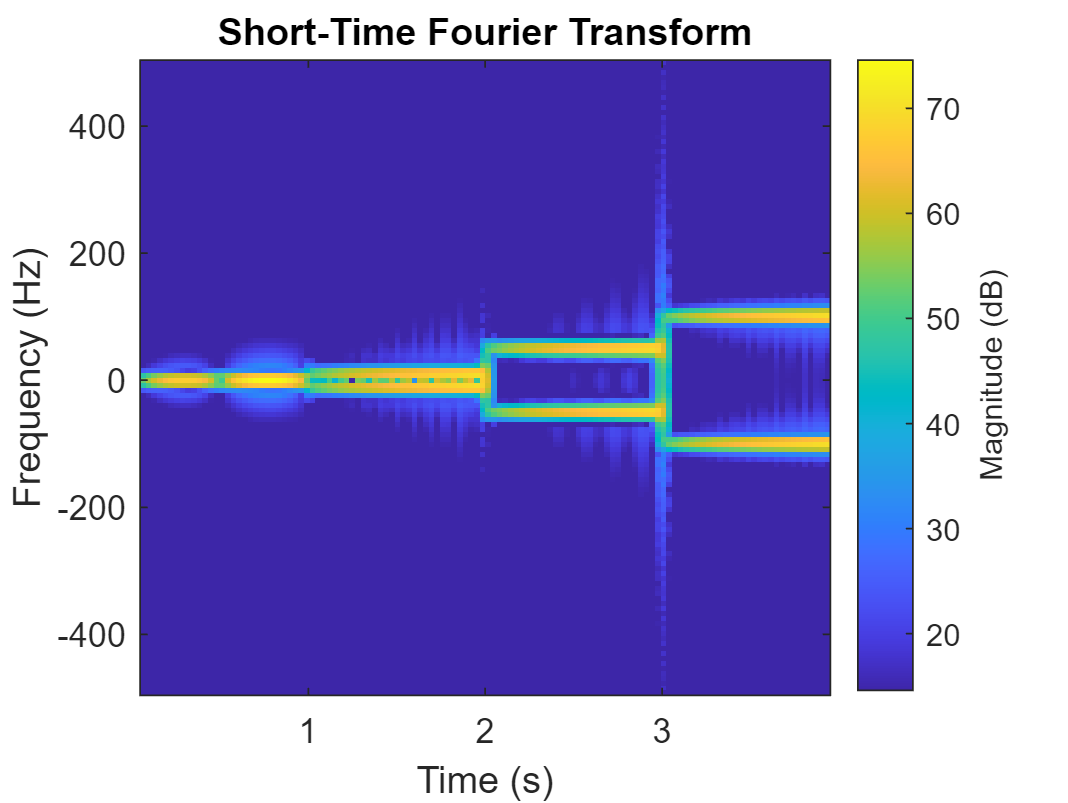

figure
stft(y_nonstat,1000,'Window',kaiser(128,5))

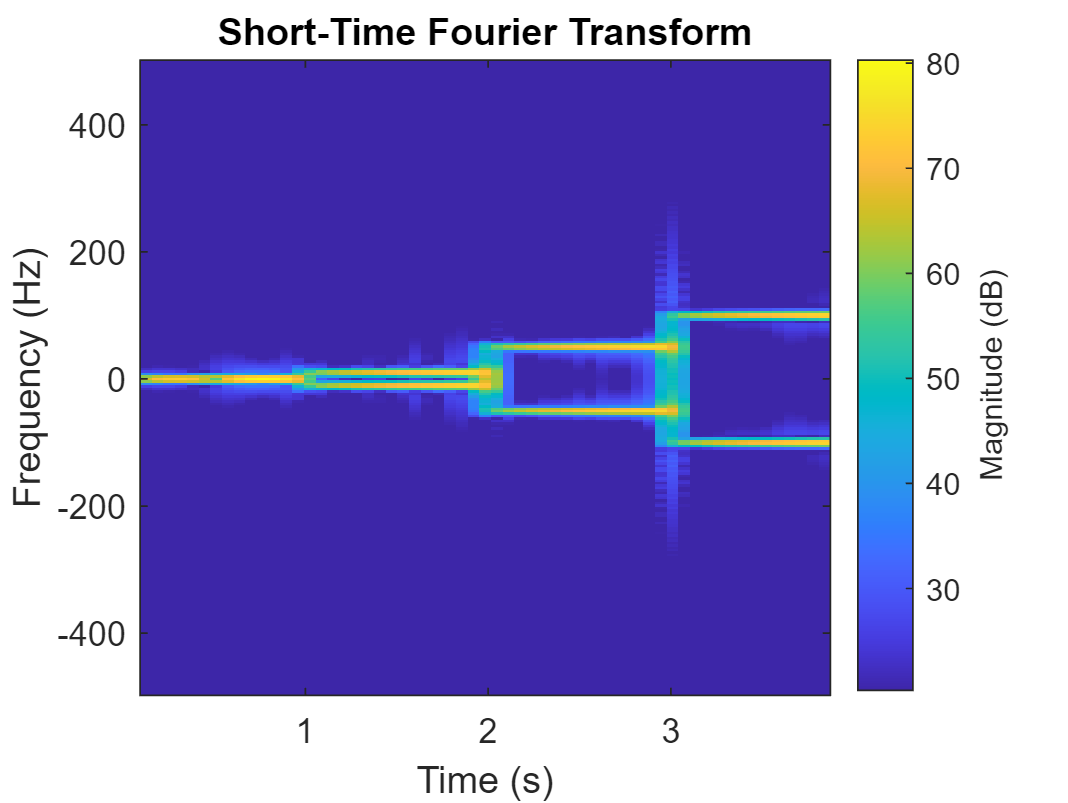


figure
stft(y_nonstat,1000,'Window',kaiser(256,5))

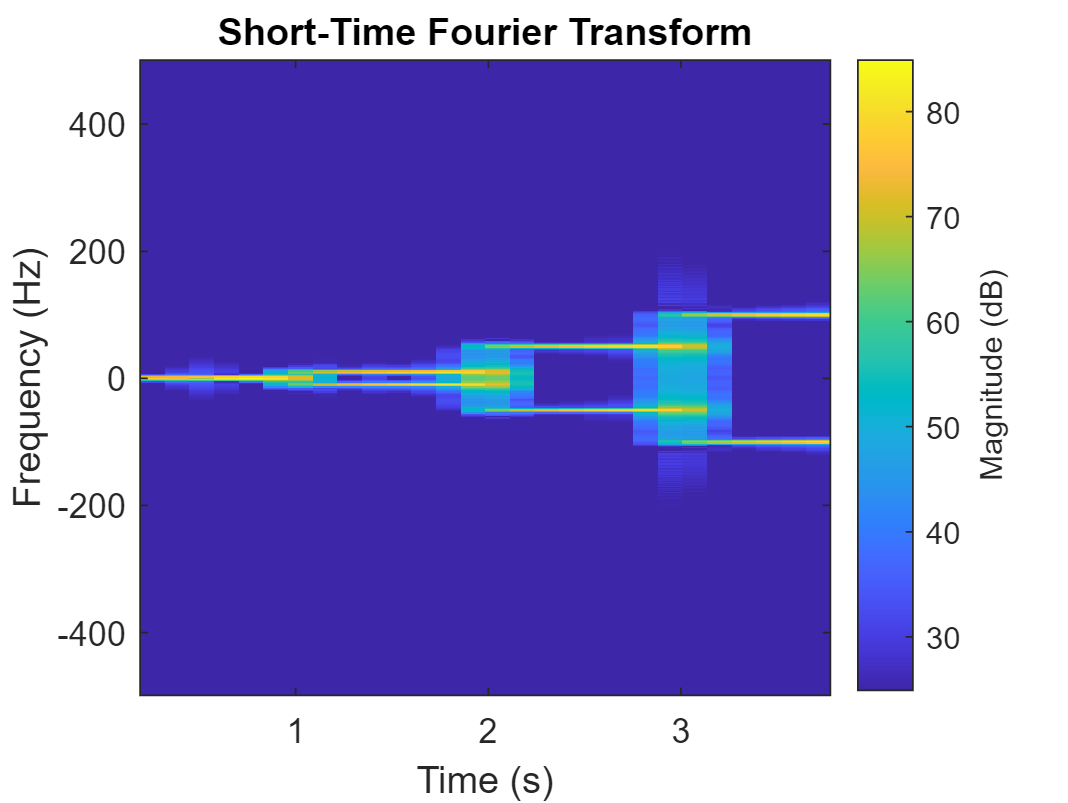

figure
stft(y_nonstat,1000,'Window',kaiser(512,5))

According to our observation: **"A wide window gives better frequency resolution but poor time resolution. A narrower window gives good time resolution but poor frequency resolution"**

E) ‘dataset.mat’ contains data from real EEG recordings. This dataset is a concatenation of multiple recording segments (trials). Repeat the analysis in sections B and D using the EEG dataset. How many trials are included in this dataset?

load("dataset.mat")

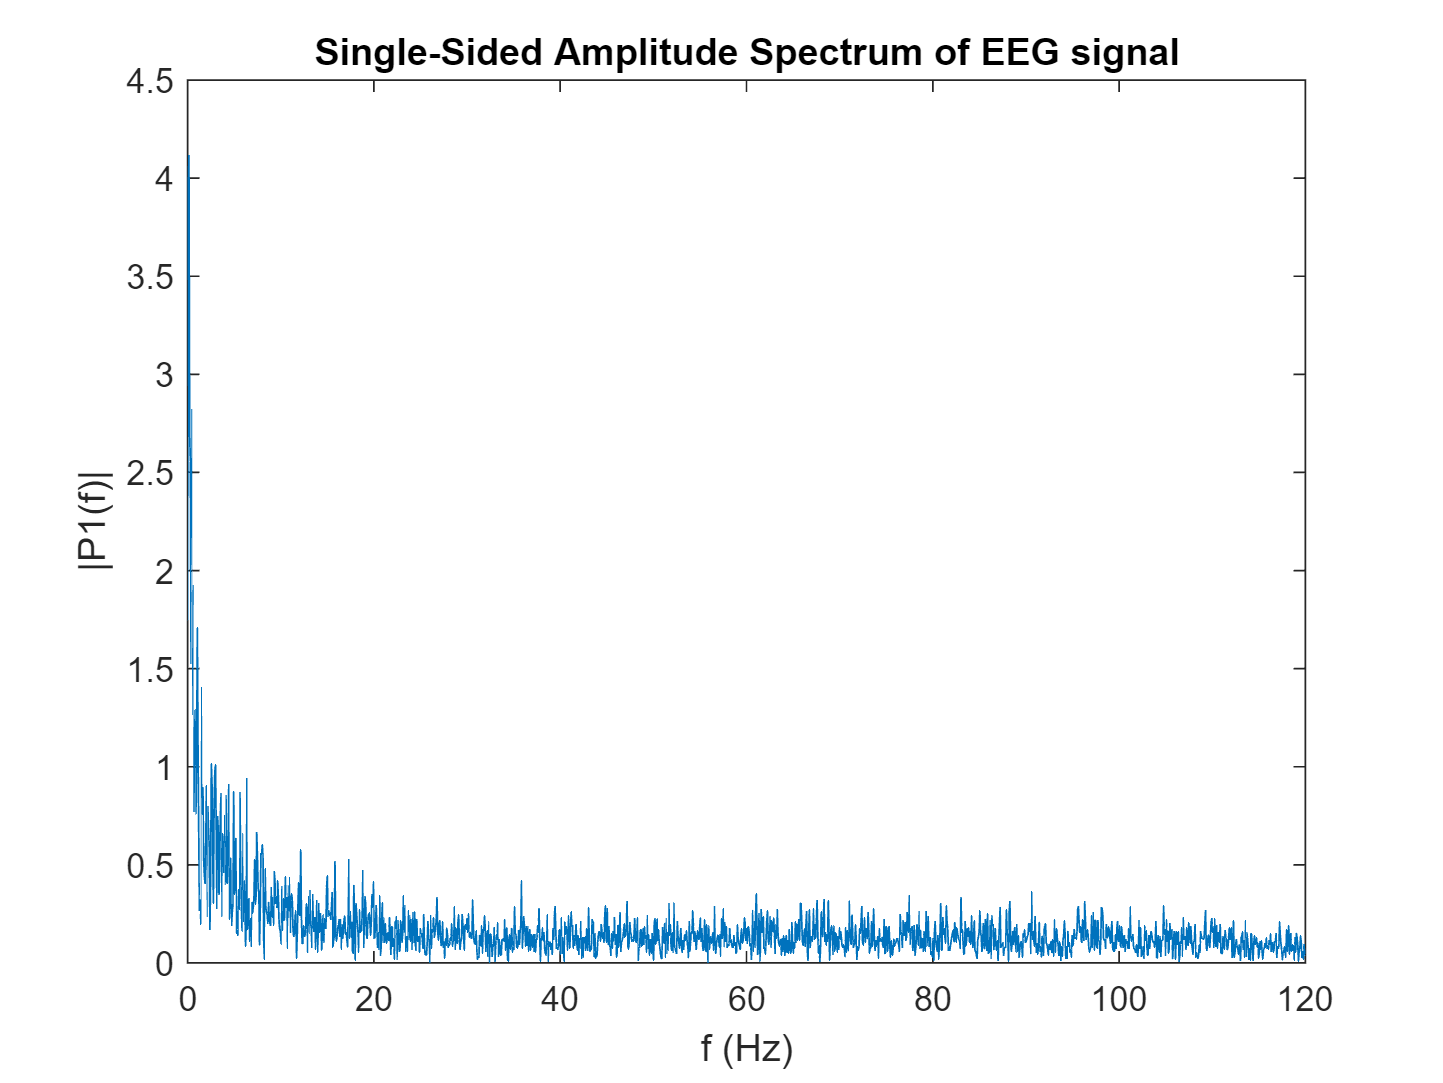

Y = fft(eeg);
L = length(eeg);
Fs = 240;
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of EEG signal')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Unfortunately we can not tell how many trails are their simply using the fft

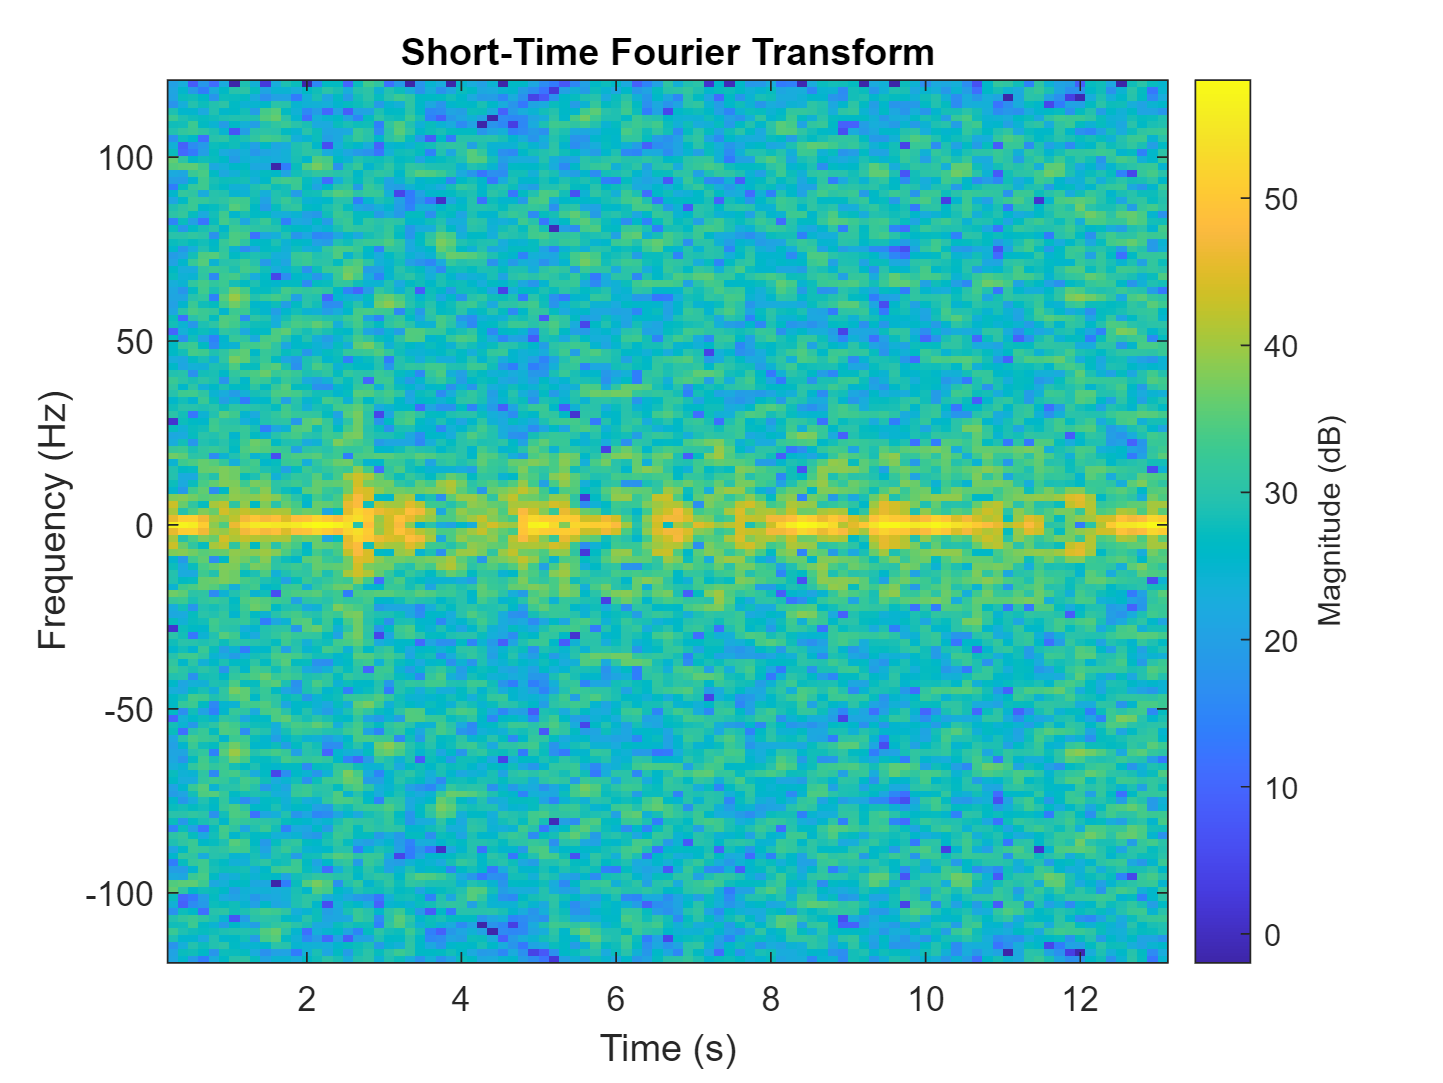

figure
stft(eeg, 240, 'Window',kaiser(128,5))

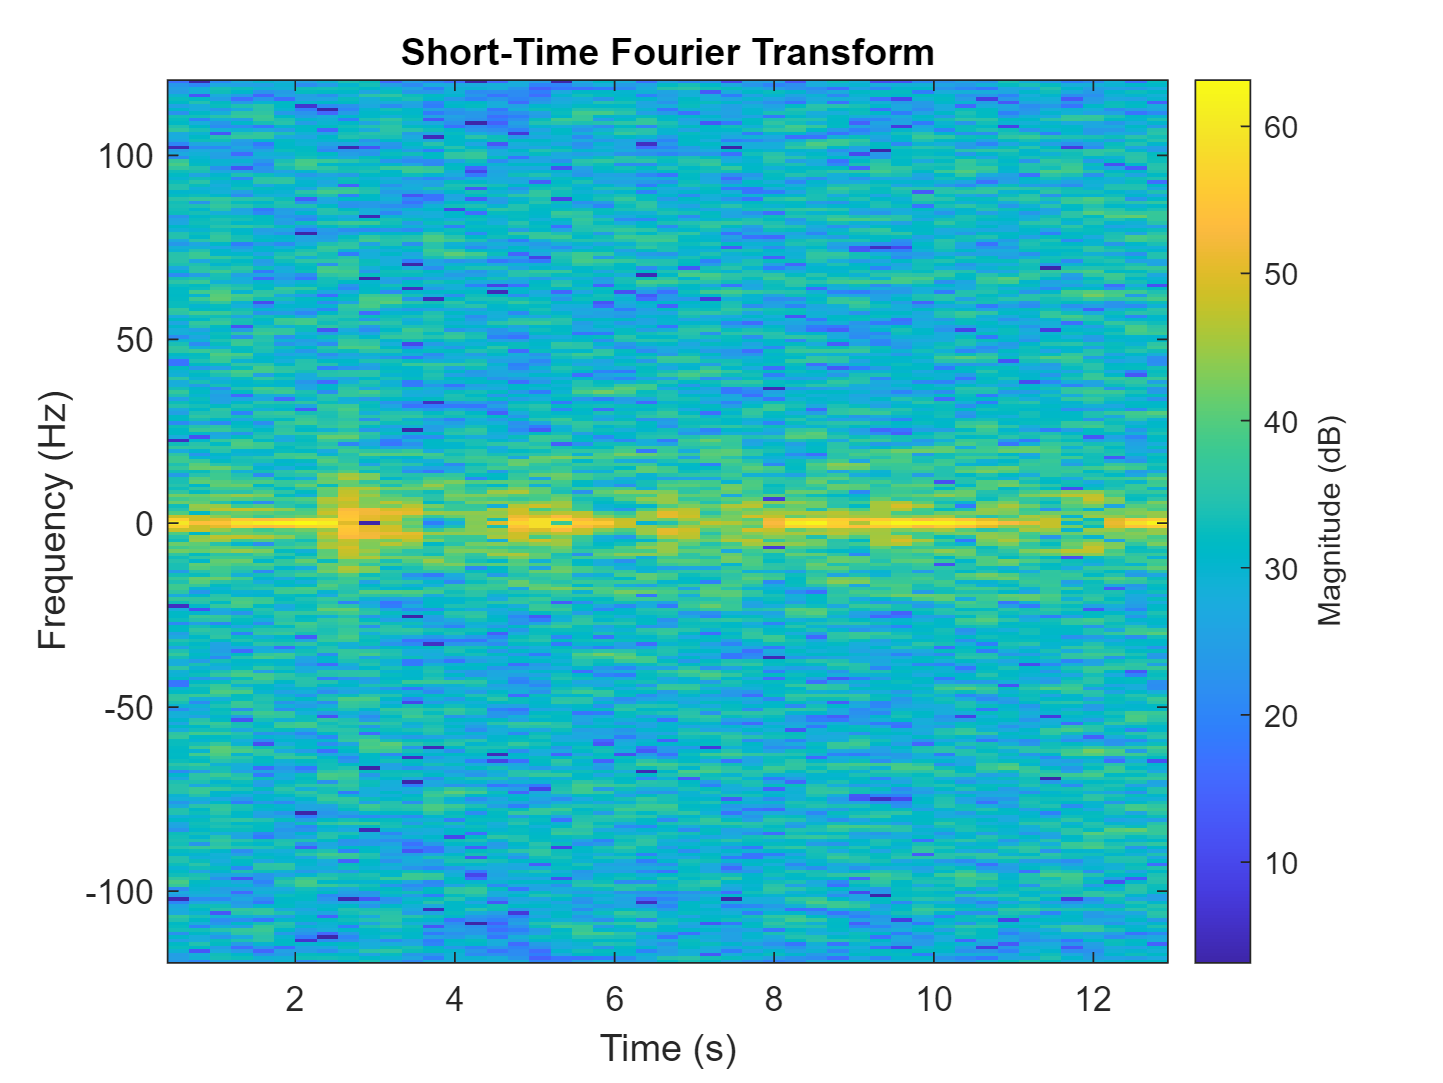

figure
stft(eeg, 240, 'Window',kaiser(256,5))

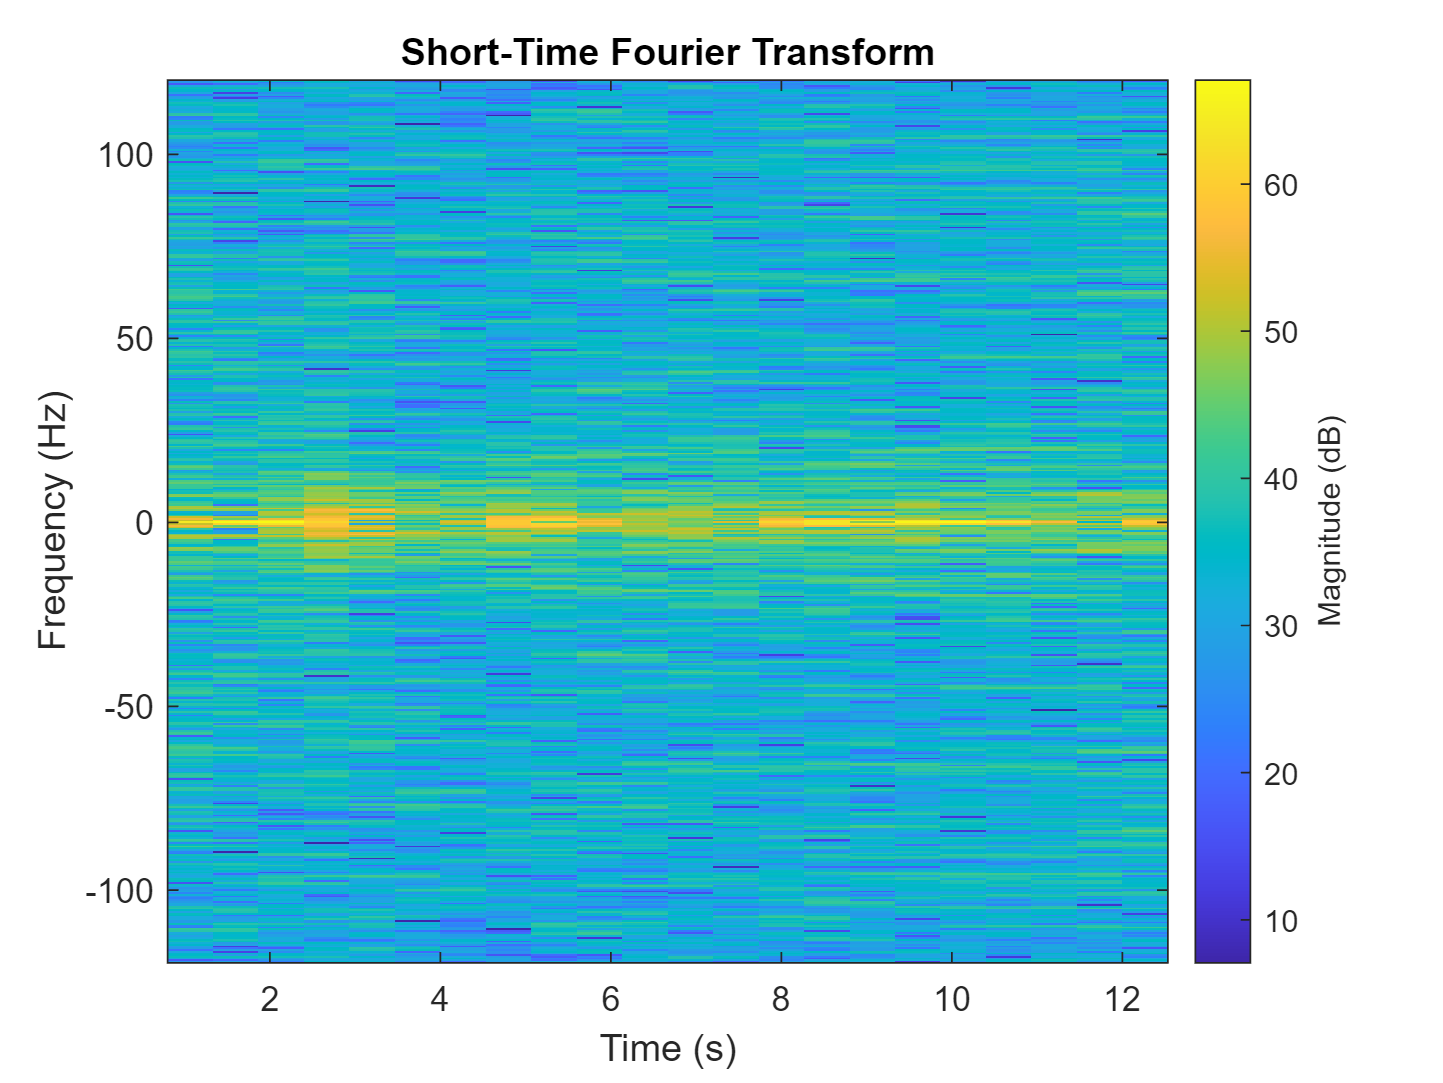

figure
stft(eeg, 240, 'Window',kaiser(512,5))

We can see that, even though the plot is not clear. But it seems that there are 5 frequencies (trails) in the dataset